# Module 2

## First method of Ziegler-Nichols

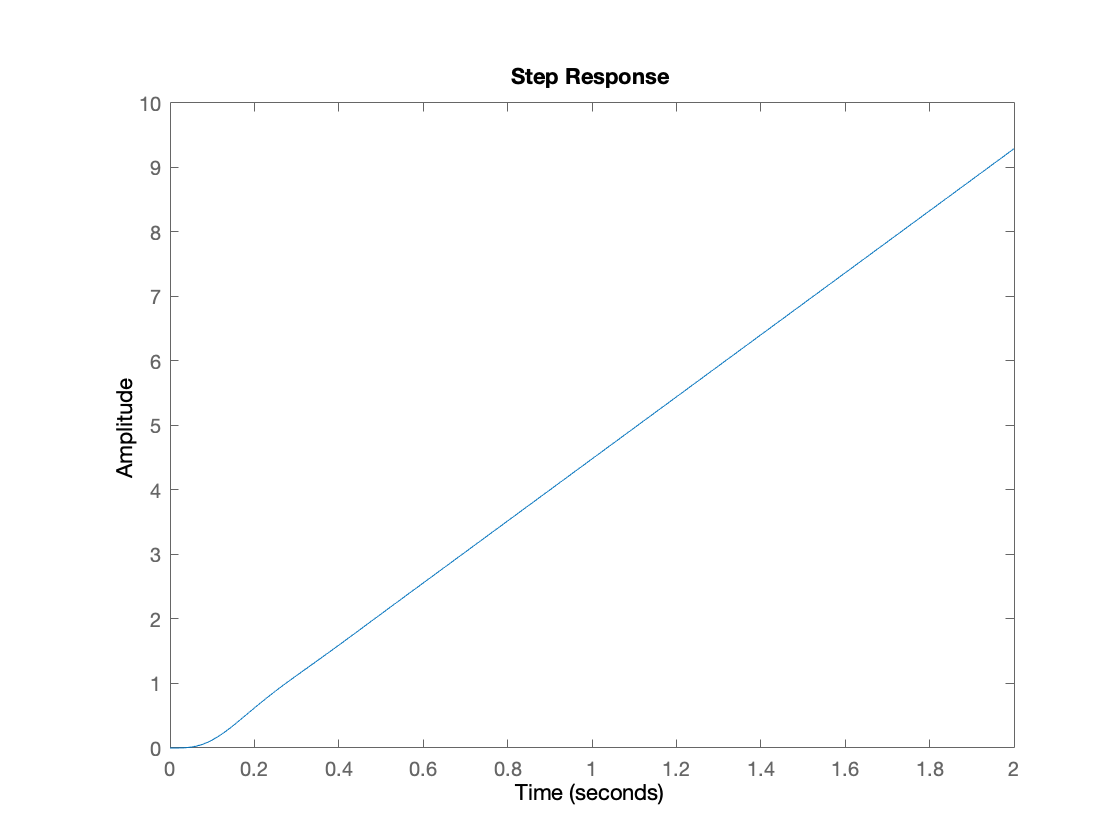

G = plant_tf();

% Computation and validation for L and R parameters
%   - For validation, plot the error between the step response and the tangent
%     defined by L and R.
% ...
t = 0:0.01:2;

step(G,t)

% Point 1: (1.55, 7.12709)
% Point 2: (0.75, 3.27961)
p1x = 1.55;
p1y = 7.12709;
p2x = 0.75;
p2y = 3.27961;

R = (p2y - p1y) / (p2x - p1x)

R = 4.8093

b = p2y - R * p2x;

L = - b / R

L = 0.0681

% Step response from reference to output
[K, ~, ~] = zn_first();

% You can use the closed loop TF function from Module1
[S_zn_first, U_zn_first, T_zn_first, V_zn_first, stability_zn_first] = closed_loop_tfs(K);
stability_zn_first

stability_zn_first = logical
   1


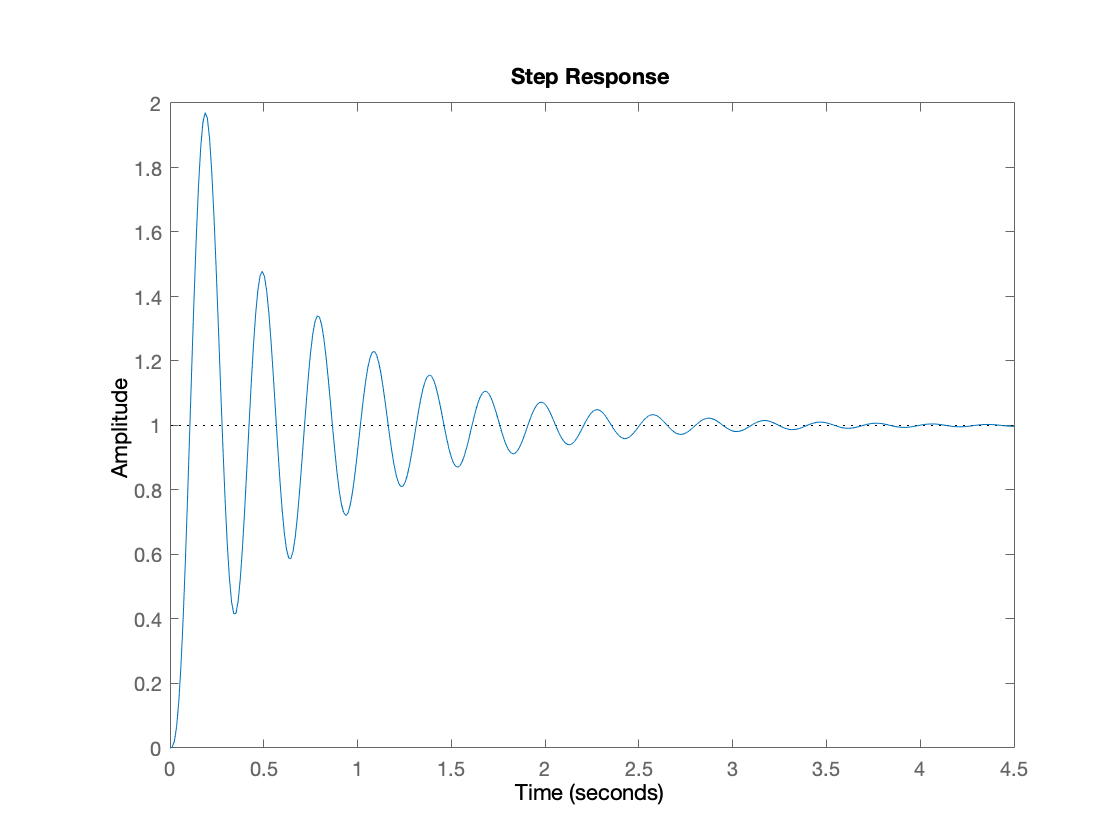

step(T_zn_first)

## Second method of Ziegler-Nichols

[K, ~] = zn_second();

% Step response from reference to output
% ...

% System response after step disturbance
% ...

## Cascade controller

% Second-order model approximation
G = plant_tf();
s = tf('s');
G1 = G * s;
% ...

[Dc_prime, gamma, zeta, omega_n] = cascade_inner();
Dc = cascade_outer();
[T_cascade, V_cascade] = cascade_tfs();

% Compare with ZN-PID controller
% ...